## Finite Burn

clear all;
clc;

% Define Parameters
params.mu = 398600; % gravitational parameter, km^3/s^2 
params.mdot = 0.025; % kg/s (made up a number that sounds reasonable for electric propulsion. Will add a real number in the future)  
params.g = 9.81; % gravity m/s^2 (probably need to use gravity at altitude but this is fine for a first look)
mu = params.mu;
g = params.g;
mdot = params.mdot;

% Initial Orbit
r1 = [-10063; -472; -12487]; % km
v1 = [-0.359; -4.950; 0.475]; % km/s
y01 = [r1; v1];

% Final Orbit
r2 = [-7704; -7223; -12077]; % km
v2 = [-2.4078; -4.249; -1.0066]; % km/s
y02 = [r2; v2];

% Spacecraft mass and ISP
Isp = 1960; % Sec using Busek USA	BIT-3	RF Ion	Iodine	https://www.nasa.gov/smallsat-institute/sst-soa/in-space_propulsion/
m0 = 200; % kg (made up, also very unrealistic for a satellite)


% Ode 45 options
options = odeset(RelTol=1e-6, AbsTol=1e-8);

% Lambert Problem Velocities
t_goal= 1 * 60 * 60; % 12 hours for the transfer
N = 0;
D = 0;
[vi,vf,vH1,vH2,theta] = LambertBattin(r1,r2,t_goal,N,D,v1,mu);

% Calculate times of the burns
Ve = (Isp * g) / 1000; % km/s         

% Burn 1
delta_v1 = norm(vi - v1);       
mf1 = m0 * exp(-delta_v1 / Ve); 
delta_m1  = m0 - mf1;                       
t1   = delta_m1 / mdot;                      

% Burn 2
delta_v3_needed = norm(vf - v2);        
mf3 = delta_m1 * exp(-delta_v3_needed / Ve);
delta_m3  = delta_m1 - mf3;
t3   = delta_m3 / mdot;

% Coast
t2 = t_goal - t1 - t3;

fprintf('Time of first burn in hours %f\n', t1/3600)

Time of first burn in hours 0.371589


fprintf('Time of coast in hours %f\n', t2/3600)

Time of coast in hours 0.526432


fprintf('Time of third burn in hours %f\n', t3/3600)

Time of third burn in hours 0.101979



 
% Defining the P vector (also making up a number for thrust and times,
% thrust = 1 mN


T =   1e-3

T = 1.0000e-03

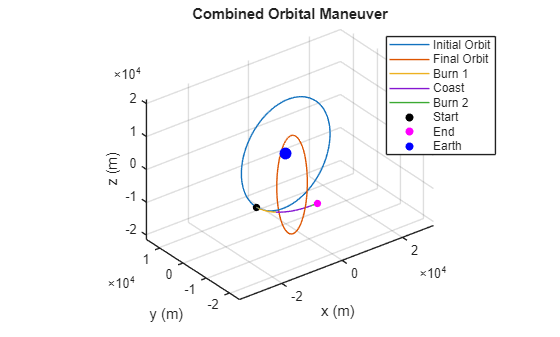

P = [t1 T T T t2 t3 T T T]';

% Simulate First Burn
tspan = [0 P(1)];
x0 = [r1; v1];
x = [r1; v1];
boolean = "True";
[t_burn1, xout1] = ode45(@(t,x)sys_dynamics(x,P(2:4),boolean,params), tspan, x0, options);

% Simulate Coast
tspan = [P(1) P(5)+P(1)];
x0 = xout1(end,:)';
boolean = "False";
[t_burn2, xout2] = ode45(@(t,x)sys_dynamics(x,P(2:4),boolean,params), tspan, x0, options);

% Simulate Second Burn
tspan = [P(5)+P(1) P(5)+P(1)+P(6)];
x0 = xout2(end,:)';
boolean = "True";
[t_burn3, xout3] = ode45(@(t,x)sys_dynamics(x,P(2:4),boolean,params), tspan, x0, options);

% Simulate orbits
tspan = [0 3600];
tspan2 = [0 100000];
%[thist1, y1] = ode45(@(t, y) orbit(t, y, params), tspan2, y01, options);
%[thist2, y2] = ode45(@(t, y) orbit(t, y, params), tspan2, y02, options);
OE1 = RV2COE(r1,v1,params);
OE2 = RV2COE(r2,v2,params);
n = 1000; % Number of points for the plot
Data_Points = linspace(0, 2*pi, n);
[i1,j1,k1] = generate_orbit_points(OE1, Data_Points);
[i2, j2, k2] = generate_orbit_points(OE2, Data_Points);

%% Concatenate full trajectory
t_all    = [t1;    t2;    t3];
xout_all = [xout1; xout2; xout3];


figure();
hold on;
plot3(i1, j1, k1, 'DisplayName', 'Initial Orbit');
plot3(i2, j2, k2, 'DisplayName', 'Final Orbit');

plot3(xout1(:,1), xout1(:,2), xout1(:,3), 'DisplayName', 'Burn 1');
plot3(xout2(:,1), xout2(:,2), xout2(:,3), 'DisplayName', 'Coast');
plot3(xout3(:,1), xout3(:,2), xout3(:,3), 'DisplayName', 'Burn 2');

scatter3(xout1(1,1),   xout1(1,2),   xout1(1,3),   30, 'k', 'filled', 'DisplayName', 'Start');
scatter3(xout3(end,1), xout3(end,2), xout3(end,3), 30, 'm', 'filled', 'DisplayName', 'End');
scatter3(0, 0, 0,   80, 'b', 'filled', 'DisplayName', 'Earth');

xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
title('Combined Orbital Maneuver');
legend; grid on; axis equal;
view(3)
hold off;

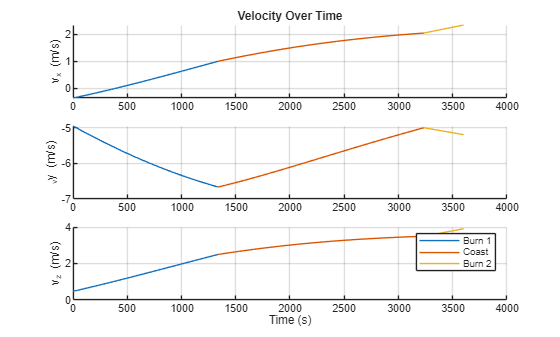


%% Plot 2: Velocities over time
figure();
subplot(3,1,1);
hold on;
plot(t_burn1, xout1(:,4)); 
plot(t_burn2, xout2(:,4)); 
plot(t_burn3, xout3(:,4));
ylabel('v_x (m/s)'); title('Velocity Over Time'); grid on;

subplot(3,1,2);
hold on;
plot(t_burn1, xout1(:,5)); 
plot(t_burn2, xout2(:,5)); 
plot(t_burn3, xout3(:,5));
ylabel('_vy (m/s)'); grid on;

subplot(3,1,3);
hold on;
plot(t_burn1, xout1(:,6)); 
plot(t_burn2, xout2(:,6)); 
plot(t_burn3, xout3(:,6));
ylabel('v_z (m/s)'); xlabel('Time (s)'); grid on;

legend('Burn 1', 'Coast', 'Burn 2');
hold off;






%%%%%%%%%%%%%%%%%% System Dynamics Function %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [xout] = sys_dynamics(x, T, boolean, params)
    % Extract values
    mu = params.mu;
    
    r = [x(1), x(2), x(3)];
    v = x(4:6);
    a = -mu/norm(r)^3;
 
    A = [0 0 0 1 0 0;
         0 0 0 0 1 0;
         0 0 0 0 0 1;
         a 0 0 0 0 0;
         0 a 0 0 0 0;
         0 0 a 0 0 0];
    
        v = x(4:6);
        normT = norm(T);


    if boolean == "True" % True if Thrust is needed
                v_hat = v / norm(v);        % unit vector along velocity
        T = normT * v_hat; 

        B = [0 0 0;
             0 0 0;
             0 0 0;
             1 0 0;
             0 1 0;
             0 0 1];

    else
        B = [0 0 0;
             0 0 0;
             0 0 0;
             0 0 0;
             0 0 0;
             0 0 0];
        T = [0;0;0];
    end

    xout = A*x + B*T;
end



%%%%%%Function to draw orbits. need to change this to orbital elements
function dydt = orbit(t,y,params)
    mu = params.mu;
    
    r = y(1:3);    % Position vector (x, y, z)
    v = y(4:6);    % Velocity vector (vx, vy, vz)

    r_norm = norm(r);   
    alpha = -(mu / r_norm^3) * r; 
    dydt = [v; alpha];  
end

%%%%% Function to convert R and V vector to Orbital elments
function OE = RV2COE(r,v,params)

    h = cross(r,v); % Angular Momentum km^2/s
    mu = params.mu; % Gravitational Param km^3/s^3
    
    normh = norm(h); % Magnitudes/Norms of the H, R, & V vectors
    normv = norm(v);
    normr= norm(r);

    khat = [0,0,1]; % Unit Vector in the Z direction
    n = cross(khat,h); % Node Vector

    e = ((normv^2-mu/normr)*r-dot(r,v)*v)/mu; % Eccentricity & its norm
    norme = norm(e);

    xi = normv^2/2-mu/normr; % Specific Mechanical Energy km^2/s^2

    if e ~= 1
        a = -mu/(2*xi); % Semimajor axis km
        p = a*(1-norme^2); % Semiparameter km
    else
        p = normh^2/mu;
        a = inf;
    end

    i = acos(h(3)/normh); % inclination
    RA = acos(n(1)/norm(n)); % Right Ascension of Ascending Node 0 - 2pi
    if n(2)<0
        RA = 2*pi-RA;
    end
    omega = acos(dot(n,e)/(norm(n)*norme)); % Arguement of Perigee 0 - 2pi
    if e(3)<0
        omega = 2*pi-omega;
    end
    nu = acos(dot(e,r)/(norme*normr)); % True Anomaly 0 - 2pi
    if dot(r,v)
        nu = 2*pi-nu;
    end
    
    omega_true = acos(e(1)/norme);
    if e(2)<0
        omega_true = 2*pi - omega_true;
    end
    u = acos(dot(n,r)/(norm(n)*normr)); % argument of Latitude 0 - 2pi
    if r(3)<0
        u=2*pi-u;
    end
    lambda_true = acos(r(1)/normr); % true longitude 0 - 2pi
    if r(2)<0
        lambda_true = 2*pi-lambda_true;
    end

    OE = [p,a,norme,i,RA,omega,nu,u,lambda_true,omega_true];
end


function [x, y, z] = generate_orbit_points(OE, Data_Points)
%OE = [p,a,norme,i,RA,omega,nu,u,lambda_true,omega_true];    
    p = OE(1);
    e = OE(3);
    incl = OE(4);
    RA = OE(5);    
    w = OE(6);
          
    n = length(Data_Points);
    x = zeros(1, n);
    y = zeros(1, n);
    z = zeros(1, n);
    
    for i = 1:n
       nu = Data_Points(i);
       r = p / (1 + e*cos(nu)); % Scalar r value
       % R in perifocal frame
       r_pf = r * [cos(nu); sin(nu); 0]; % Vector                                                                                                                                                                                                                
       
       % Rotation matrices Perifocal (PQW) to Earth Centered Inertial Frame
       % (ECI) 3-1-3 rotation
       R3_RA = [cos(-RA) sin(-RA) 0;
               -sin(-RA) cos(-RA) 0;
               0 0 1];
       R1_i = [1 0 0; 
               0 cos(-incl) sin(-incl);
               0 -sin(-incl) cos(-incl)];
       R3_w = [cos(-w) sin(-w) 0;
               -sin(-w) cos(-w) 0;
               0 0 1];
        
       % Transform to inertial frame
       r_eci = R3_RA * R1_i * R3_w * r_pf;      
       x(i) = r_eci(1);
       y(i) = r_eci(2);
       z(i) = r_eci(3);
    end
end

%%%%%%%%%%%%%% Everything below is from COMPLETE SOLUTION TO THE LAMBERT PROBLEM WITH PERTURBATIONS AND TARGET STATE SENSITIVITY
% Need to finish stress testing it for case 3 and 4

function [v1,v2,vH1,vH2,theta] = LambertBattin(r1,r2,t,N,D,v_1,mu)
% r1 = initial position
% r2 = final (target) position
% t = time of flight
% N = integer number of whole revs
% D = direction of motion flag (-1,0,+1)
% -1 = long way, +1 = short way, 0 = algorithm decides
% v_1 = pre-maneuver velocity
% mu = gravitational param
% v1 = initial velocity
% v2 = final velocity
% vH1 = multi-rev high-energy initial velocity
% vH2 - multi-rev high energy final velocity
% theta = transfer angle 0-2pi
    A = dot(r1,r2)/(norm(r1)*norm(r2));
    if A > 1.0
        A = 1.0;
    end
    if A <-1.0
        A = -1.0;
    end
    
    theta = acos(A); % Transfer Angle
    if (D==-1) || (D==0 && dot(cross(r1,v_1),cross(r1,r2))<0)
        theta = 2 * pi - theta; %long way transfer
    end
    
    c=norm(r2-r1);

    s=1/2*(norm(r1)+norm(r2)+c);

    lambda = 1/s*sqrt(norm(r1)*norm(r2))*cos(theta/2);

    L = ((1-lambda)/(1+lambda))^2;
    m = (8*mu*t^2)/(s^3*(1+lambda)^6);
    if N>0
        x =1+4*L;
    else
        x=L;
    end
    xdiff=1;
    while xdiff>1e-6

        if N>0
            h1 =((L+x)^2/(4*x^2*(1+2*x+L))) * (3*(1+x)^2*((N*pi/2+atan(sqrt(x)))/sqrt(x))-(3+5*x));
            a = m/(4*x^2*(1+2*x+L));
            h2 = a*((x^2-x*(1+L)-3*L)* ((N*pi/2+atan(sqrt(x))/sqrt(x)))+(3*L+x));
        else
            etta = x/(sqrt(1+x)+1)^2;
            %solve for etta, use the top-down method
            bn= 3;
            dn= 1;
            un= 8*(sqrt(1+x)+1)/bn;
            eps=un;
            i=1;
            while abs(un)>1*10^(-12)
                bp=bn;
                dp=dn;
                up=un;
                i=i+1;
                if i ==2
                    an=-1;
                    bn=5+etta;
                elseif i == 3
                    an = -9*etta/7;
                    bn=1;
                else
                    an=-etta*i^2/(4*i^2-1);
                    bn=1;
                end
                dn=1/(1-an*dp/bp/bn);
                un = up*(dn-1);
                eps = eps+un;
            end
            h1 = ((L+x)^2*(1+3*x+eps))/ ((1+2*x+L)*(4*x+eps*(3+x)));
            h2 = (m*(x-L+eps))/((1+2*x+L)*(4*x+eps*(3+x)));
        end
        B = 27*h2 /(4*(1+h1)^3);
        u = B/(2*(sqrt(1+B)+1));
        %Solve for K, use top-down method
        bn = 1; dn=1; un=1/3; K=un;n=0; evenflag = 1;
        while abs(un)>1*10^(-12)
            bp=bn;
            dp=dn;
            up=un;
            if evenflag==1
                an = (-2*u*(3*n+2)*(6*n+1)) / (9*(4*n+1)*(4*n+3));
                evenflag = 0; n=n+1;
            else
                an = (-2*u*(3*n+1)*(6*n-1)) / 9/(4*n-1)/(4*n+1);
                evenflag=1;
            end
            dn = 1/(1-an*dp/bp/bn);
            un = up * (dn - 1);
            K = K + un;
        end
    
        y = (1+h1)/3*(2+sqrt(1+B)/(1+2*u*K^2));
        xnew = sqrt(((1-L)/2)^2+m/y^2)-(1+L)/2;
        xdiff=abs(xnew-x);
        x=xnew;
    end
    
    p = (2*norm(r1)*norm(r2)*y^2*(1+x)^2*sin(theta/2)^2) / (m*s*(1+lambda)^2);
    eps = (norm(r2)-norm(r1))/norm(r1);
    e = sqrt((eps^2+4*norm(r2)/norm(r1)*sin(theta/2)^2*((L-x)/(L+x))^2) / (eps^2+4*norm(r2)/norm(r1)*sin(theta/2)^2));
    
    [v1,v2] = hodograph_velocity_algorithm(r1,r2,t,v_1,theta,p,e,mu);
    %% ---------------Multi-rev High-energt Solution ------------%%%%
    if N>0
        x = 1e-20;
        xdiff=1;
        while xdiff>1e-6
            h1 = ((L+x)*(1+2*x+L))/(2*(L-x^2));
            h2 = (m*sqrt(x))/(2*(L-x^2))*((L-x^2)*((N*pi/2+atan(sqrt(x)))/sqrt(x))-(L+x));
            B = 27*h2/(4*(sqrt(x)*(1+h1))^3);
            if B<0
                F = 2*cos(1/3*acos(sqrt(B+1)));
            else
                A = nthroot(sqrt(B)+sqrt(B+1),3);
                F = A+1/A;
            end
            y = 2/3*sqrt(x)*(1+h1)*(sqrt(B+1)/F+1);
            xnew = 1/2*((m/y^2-(1+L))-sqrt((m/y^2-(1+L))^2-4*L));
            xdiff = abs(xnew - x);
            x = xnew;
        end
    a = (s*(1+lambda)^2*(1+x)*(L+x))/(8*x);

    p = (2*norm(r1)*norm(r2)*sin(theta/2)^2*(1+x))/(s*(1+lambda)^2*(L+x));
    e = sqrt(1-p/a);
    [vH1,vH2] = hodograph_velocity_algorithm(r1,r2,t,v_1,theta,p,e,mu);
    else
        vH1 = zeros(length(v1));
        vH2 = zeros(length(v2));
    end
end



function [v1,v2] = hodograph_velocity_algorithm(r1,r2,t,v_1,theta,p,e,mu)
    L_180 = 1.0;
    A = mu*(1/norm(r1)-1/p);
    B = (mu*e/p)^2-A^2;
    if B<=0
        x1=0;
    else 
        x1=-sqrt(B);
    end
    if abs(sin(theta))<L_180/norm(r2)
        n_hat = cross(r1,v_1)/norm(cross(r1,v_1));
        if e<1 
            p = 2*pi*sqrt(p^3/(mu*(1-e^2)^3));
            if mod(t,p)>(p/2)
                x1=-x1;
            end
        end
    else
        n_hat = cross(r1,r2)/norm(cross(r1,r2));
        if mod(theta,2*pi)>pi
            n_hat=-n_hat;
        end
        y2a = mu/p - x1*sin(theta)+A*cos(theta);
        y2b = mu/p + x1*sin(theta)+A*cos(theta);
        if norm(mu/norm(r2) - y2b)<norm(mu/norm(r2)-y2a)
            x1=-x1;
        end
    end
    v1 = (sqrt(mu*p)/norm(r1))*((x1/mu)*r1+cross(n_hat,r1)/norm(r1));
    x2 = x1*cos(theta)+A*sin(theta);
    v2 = (sqrt(mu*p)/norm(r2))*((x2/mu)*r2+cross(n_hat,r2)/norm(r2));
end



function [phi] = LambertSTM(r1,r2,t,N,D,v_1,mu,fHE) %phi(t2,t1)
    delr = 0.1; %meters
    A = dot(-r1,r2)/(norm(r1)*norm(r2));
    if A>1.0
        A=1.0;
    end
    if A<-1.0
        A=-1.0;
    end
    phi = acos(A); %Angle between r2 and r1
    if phi<pi/900 %0.2 degrees
        Rhat = r2/norm(r2);
        Nhat = cross(r2,v_1)/(norm(cross(r2,v_1)));
        That = cross(Nhat,Rhat); % RTH unit vectors
        [R]=[Rhat',That',Nhat']; % RTN unit vectors form the rows of the matrix R
        rT = norm(r2)*tan(pi/360); %0.5 degrees transverse
        r2 = r2 +R'*[0;rT;0];
    end
    [v1,v2,vh1,vh2,theta] = LambertBattin(r1,r2,t,N,D,v_1,mu); % nominal solution
    if (N>0) && (fHE ==1)
        v1 = vh1;
        v2 = vh2;
    end
    for i=1:3
        r2p = r2;
        r2p(i)=r2p(i)+delr;
        [v1p,v2p,vh1,vh2,theta] = LambertBattin(r1,r2p,t,N,D,v_1,mu);
        if (N>0) && (fHE == 1)
            v1p=vh1;
            v2p=vh2;
        end
        delv1(1:3,i) = v1p-v1; % the ith column of matrix delv1
        delv2(1:3,i)=v2p-v2;
    end
    phi2 = delr*inv([delv1]);
    phi4 = delv2*inv([delv1]);
    for i =1:3
        r1p=r1;
        r1p(i)=r1p(i)+delr;
        [v1p,v2p,vh1,vh2,theta] = LambertBattin(r1p,r2,t,N,D,v_1,mu);
        if (N>0) & (fHE == 1)
            v1p=vh1;
            v2p=vh2;
        end
        delv1(1:3,i) = v1p-v1; % the ith column of matrix delv1
        delv2(1:3,i)=v2p-v2;
    end
    phi3 = (delv2-phi4*delv1)/delr;
    phi1 = (inv(phi4)*(eye(3)+phi3*phi2'))';
    phi = [phi1, phi2;phi3,phi4]; 
end


function [v1,v2] = PerturbedLambert(r1,r2,t,N,D,v_1,mu,fHE)
    delrmin=0.1;
    r2_miss = 2*delrmin;
    delr2 = zeros(size(r2));
    r2_orig = r2;
    cnt = 0;
    max_iterations = 50;
    while r2_miss>delrmin
        cnt = cnt+1;
        if cnt> max_iterations
            break
        end
        r2 = r2-delr2;
        [v1,v2,vH1,vH2,theta]=LambertBattin(r1,r2,t,N,D,v_1,mu);
        if N>0 && fHE ==1
            v1=vH1;
            v2 = vH2;
        end
        %[r2p,v2p]= propagate_with_perturbations(r1,v1,t);
        delr2 = r2p-r2_orig;
        r2_miss=norm(delr2)
    end
    v2 = v2p;
end